# 数字图像处理 作业10

2022年5月20日

阮泉源 201930033629

img = imread('circuit.jpg');
img = rgb2gray(img);
img = im2double(img);

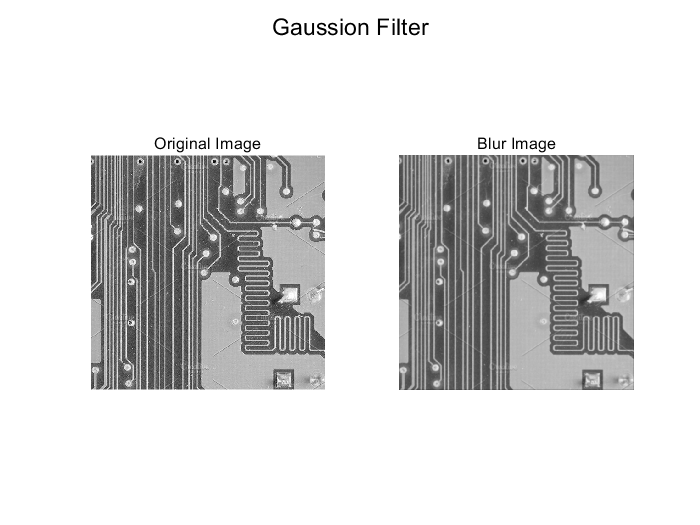

figure;
gausFilter = fspecial('gaussian',[10 10], 1);      %matlab 自带高斯模板滤波
blur=imfilter(img, gausFilter, 'conv');
subplot(1, 2, 1);
imshow(img);
title('Original Image')
subplot(1, 2, 2);
imshow(blur);
title('Blur Image')
suptitle('Gaussion Filter')

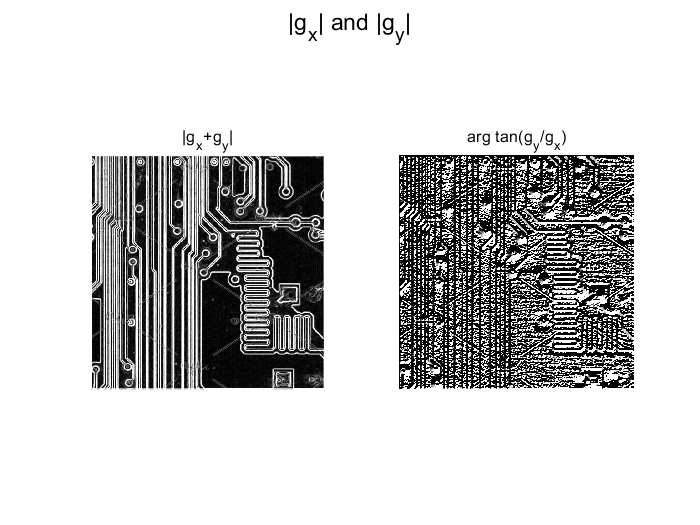

M = sobel_filter(blur);
figure;
subplot(1, 2, 1);
imshow(abs(M));
title('|g_x+g_y|')
subplot(1, 2, 2);
imshow(angle(M));
title('arg tan(g_y/g_x)')
suptitle('|g_x| and |g_y|')

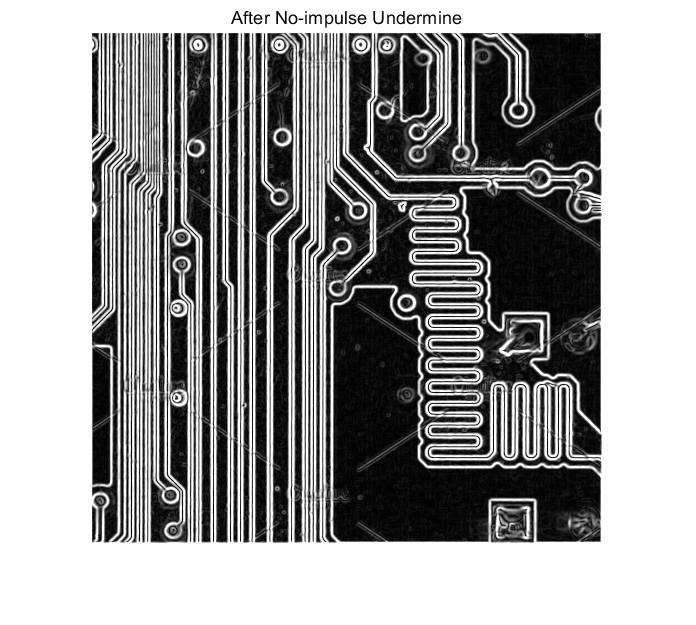

g_N = notImpulseUndermine(M);
figure;
imshow(g_N);
title('After No-impulse Undermine')

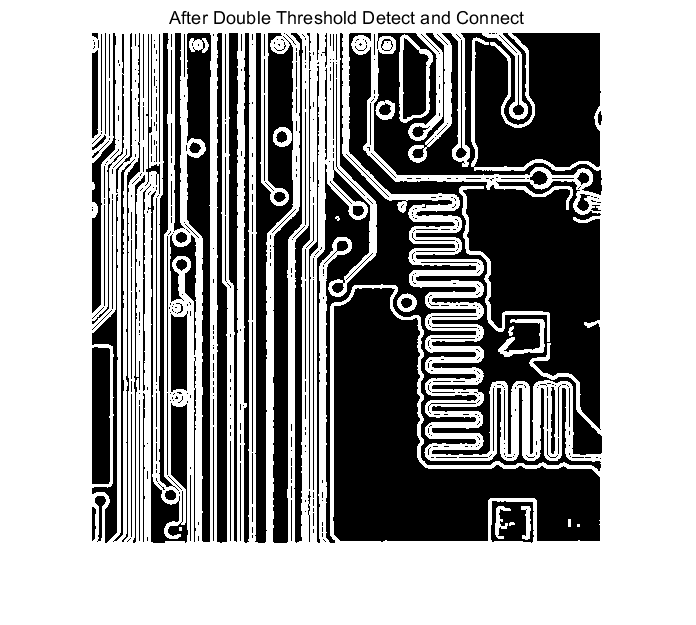

out = biThres(g_N, 0.7,  0.6);
figure;
imshow(out);
title('After Double Threshold Detect and Connect')

本次使用比较复杂，遇到了很多问题，最后收获了很多。

下面将边缘计算的过程封装为三个函数。

首先是使用x轴与y轴的Sobel算子进行相关运算，获得$M=g_x +i\times g_y \;$。

function [M] = sobel_filter(image)
Sobel_x = [-1, 0, 1; -2, 0, 2; -1, 0, 1];
Sobel_y = [1, 2, 1; 0, 0, 0; -1, -2, -1];

g_x = xcorr2(image, Sobel_x);
g_y = xcorr2(image, Sobel_y);

M = g_x+1i*g_y;
end

然后使用非极值抑制去掉非边缘点。

function [g_N] = notImpulseUndermine(M)
[w, h] = size(M);
g_N = zeros(w, h);
for i=2:w-1
    for j=2:h-1
        a = angle(M(i, j));
        if a<deg2rad(22.5) && a>deg2rad(-22.5) || a<deg2rad(-157.5) || a>deg2rad(157.5)
            if(M(i, j)>=M(i, j+1) && M(i, j)>=M(i, j-1))
                g_N(i, j) = M(i, j);
            end
        elseif  a<deg2rad(67.5) && a>deg2rad(22.5) || a<deg2rad(-112.5) && a>deg2rad(-157.5)
            if(M(i, j)>=M(i-1, j+1) && M(i, j)>=M(i+1, j-1))
                g_N(i, j) = M(i, j);
            end
        elseif  a<deg2rad(112.5) && a>deg2rad(67.5) || a<deg2rad(-67.5) && a>deg2rad(-112.5)
            if(M(i, j)>=M(i+1, j) && M(i, j)>=M(i-1, j))
                g_N(i, j) = M(i, j);
            end
        elseif  a<deg2rad(157.5) && a>deg2rad(112.5) || a<deg2rad(-22.5) && a>deg2rad(-67.5)
            if(M(i, j)>=M(i-1, j-1) && M(i, j)>=M(i+1, j+1))
                g_N(i, j) = M(i, j);
            end
        end
    end
end
g_N = abs(M(2:w-1, 2:h-1));  
end

使用双阈值和连接分析方法检测并连接边缘点。

function [image] = biThres(M, TH, TL)
[w, h] = size(M);
g_NH = M>TH;
g_NL = M>TL;
g_NL = g_NL-g_NH;
mask = zeros(w, h);
for i=2:w-1
    for j=2:h-1
        if g_NH(i, j)
            mask(i-1:i+1, j-1:j+1) = g_NL(i-1:i+1, j-1:j+1);
        end
    end
end
g_NL = mask.*g_NL;
image = g_NH+g_NL;
end